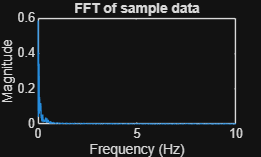

% Assuming 'noisy_lidar' is your data array
noisy_lidar = transpose(smplH(2,:));
t           = transpose(smplH(1,:));
Fs = 20; % Sample rate in Hz (Replace with your actual LIDAR refresh rate)
L = length(noisy_lidar); % Number of samples

% Perform the FFT
Y = fft(noisy_lidar);

% Calculate the two-sided spectrum, then the single-sided spectrum
P2 = abs(Y/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain vector
f = Fs*(0:floor(L/2))/L;

% Plot Figure 7(a)
figure;
plot(f, P1);
title('FFT of sample data');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


f_cut = 1.4; % Cut-off frequency from the text
order = 1;   % 1st order filter from the text

% Normalize the cut-off frequency
% Nyquist frequency is Fs/2
Wn = f_cut / (Fs/2); 

% Design the Butterworth filter (generates transfer function coefficients b and a)
[b, a] = butter(order, Wn, 'low');

butter requires one of the following:
  DSP System Toolbox
  Signal Processing Toolbox


% Apply the filter to the data
% We use 'filter' to simulate real-time processing, which inherently introduces the delay
filtered_lidar = filter(b, a, noisy_lidar);

% Plot Figure 7(b)
% Assuming 't' is your time vector
figure;
plot(t, noisy_lidar, 'k', t, filtered_lidar, 'r');
title('Filtered sample data');
xlabel('Time (s)');
ylabel('Height (m)');
legend('Raw LIDAR', 'Filtered LIDAR');